# MPU6050 - Analyse Bruit - Sans Mouvement - Donnée DMP

Ce fichier présente le bruit qui est présents lors des lectures de l'accéléromètre et du gyroscope en mode DMP afin de mieux les comprendres.

Le fichier 'DATA_sans_mouvement_1heure.TXT' contient les lectures de l'accéléromètre et gyroscope de IMU MPU6050 en mode DMP et du magnetomètre HMC5883L pendant une periode de une (1) heure sans mouvement.

Le fichier de donné à la stracuture suivante pour chaque lecture.

`dt:0.0350                     `est le delta entre la dernière lecture et la présente

`accel:6,-6,8207               `valeur d'accélération brute obtenu à travers une lecture de l'accéléromètre en mode DMP

`laccel:1,-4,14                `accélération linéaire est l'ensemble des vecteurs (x,y,z) d'accélération brute moin 

                              le vecteur d'accélération gravitationel extrait du quaternion.

`laccelw:1,3,14                `accélération linéaire en référentiel terrestre est  l'ensemble des vecteurs (x,y,z) 

                              d'accélération linéaire après une rotation selon l'orientation du quaternion.

`g:0.00,-0.00,1.00             `le vecteur d'accélération gravitationel extrait du quaternion.

`gyro:0,-1,0                   `valeur du gyroscope brute en mode DMP 

`mag:-152.23,189.50,-426.12    `valeur du gyroscope brute 

`q:-0.26,-0.00,0.00,-0.96      `valeur du quaternion obtenu à travers une lecture du DMP

`heading:141.38                `la direction en º, à partir des valeurs du magétomètre.

`TotalTime:80.0278             `les valeurs ci-dessus on été obtenu à ce moment *t*

# Chargement des données brutes

close all;                    % fermeture de tous les figures
clear;                        % effacer tous les variables
clc;                       % effacer tous les commndes du terminal

[ accel, laccel, laccelw, g, rawGyro, rawMag, Q, heading, avgDt, totalTime] = loadDMPSensorsData('DATA_sans_mouvement_80secs.TXT');

# Auto Calibration du Digital Motion Processor (DMP)

Nous avons observé une période d'auto-calibration pendant les premières secondes de lecture de donnée du capteur MPU6050 en mode Digital Motion Processor (DMP).

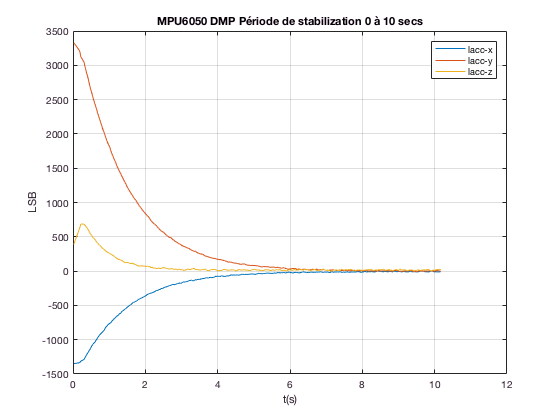

idx10 = int32(10.0 / avgDt);
figure
plot(laccel(1:idx10,4), laccel(1:idx10,1), laccel(1:idx10,4), laccel(1:idx10,2), laccel(1:idx10,4), laccel(1:idx10,3));
title 'MPU6050 DMP Période de stabilization 0 à 10 secs';
legend({'lacc-x' 'lacc-y' 'lacc-z'});
grid 'on';
ylabel 'LSB';
xlabel 't(s)';

Il semble qu'après 30 secondes, le capteurs soit stabilisé. Alors, nous allons concentrer notres analyse des données une fois 30 secondes écoulés.

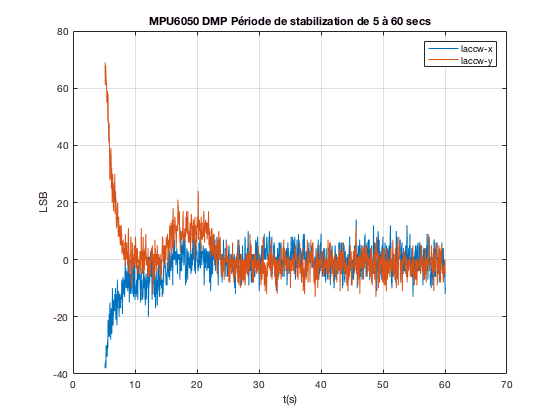

idx5 = int32(5.0 / avgDt);
idx60 = int32(60.0 / avgDt);
figure
plot( laccel(idx5:idx60,4), laccel(idx5:idx60,1), laccel(idx5:idx60,4), laccel(idx5:idx60,2));
title 'MPU6050 DMP Période de stabilization de 5 à 60 secs';
legend({'laccw-x' 'laccw-y'});
grid 'on';
ylabel 'LSB';
xlabel 't(s)';

Nous prennons un sous ensemble des données aprés aproximativement 30 secondes d'écoulées.

indexApresStab = int32(30.0 / avgDt);

sub_timestamp = accel(indexApresStab+1:end,4);
sub_accel = accel(indexApresStab+1:end,:);
sub_laccel = laccel(indexApresStab+1:end,:);
sub_laccelw = laccelw(indexApresStab+1:end,:);
sub_rawGyro = rawGyro(indexApresStab+1:end,:);
sub_rawMag = rawMag(indexApresStab+1:end,:);
sub_Q = Q(indexApresStab+1:end,:);
sub_g = g(indexApresStab+1:end,:);
sub_heading = heading(indexApresStab+1:end,:);


# Comparaisons des trois (3) différentes lecture de l'accéléromètre offertent par le pilote MPU6050 en mode DMP.

## Compariason pour l'axe des X

accel : l'ensemble de vecteur (x,y,z) d'accélération brute obtenu à travers des lectures de l'accéléromètre en mode DMP.

laccel : l'ensemble de vecteur (x,y,z) d'accélération linéaire est l'ensemble des vecteurs (x,y,z) d'accélération brute moin le vecteur d'accélération gravitationel extrait du quaternion.

laccelw : l'ensemble de vecteur (x,y,z) d'accélération linéaire en référentiel terrestre est  l'ensemble des vecteurs (x,y,z) d'accélération linéaire après une rotation selon l'orientation du quaternion.

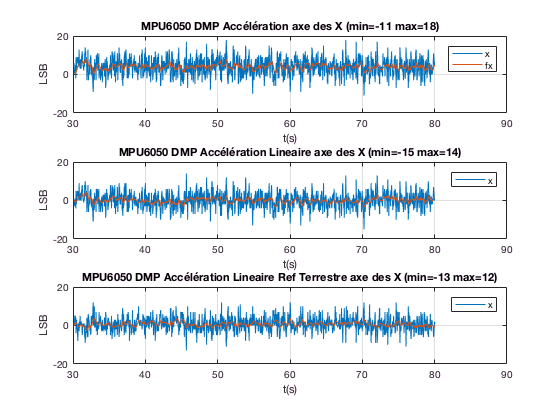

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), sub_accel(:,1), sub_timestamp(:), EMA(sub_accel(:,1),0.1, 0));
str = ['MPU6050 DMP Accélération axe des X (min=',num2str(min(sub_accel(:,1))),' max=',num2str(max(sub_accel(:,1))), ')'];
title(ax1,str);
legend(ax1, {'x' 'fx'});
grid(ax1, 'on');
ylabel(ax1,'LSB');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), sub_laccel(:,1), sub_timestamp(:), EMA(sub_laccel(:,1),0.1, 0));
str = ['MPU6050 DMP Accélération Lineaire axe des X (min=',num2str(min(sub_laccel(:,1))),' max=',num2str(max(sub_laccel(:,1))), ')'];
title(ax2,str);
legend(ax2, 'x');
grid(ax2, 'on');
ylabel(ax2,'LSB');
xlabel(ax2,'t(s)');

plot(ax3,sub_timestamp(:), sub_laccelw(:,1), sub_timestamp(:), EMA(sub_laccelw(:,1),0.1, 0));
str = ['MPU6050 DMP Accélération Lineaire Ref Terrestre axe des X (min=',num2str(min(sub_laccelw(:,1))),' max=',num2str(max(sub_laccelw(:,1))), ')'];
title(ax3,str);
legend(ax3, 'x');
grid(ax3, 'on');
ylabel(ax3,'LSB');
xlabel(ax3,'t(s)');

## Comparaison pour l'axe des Y

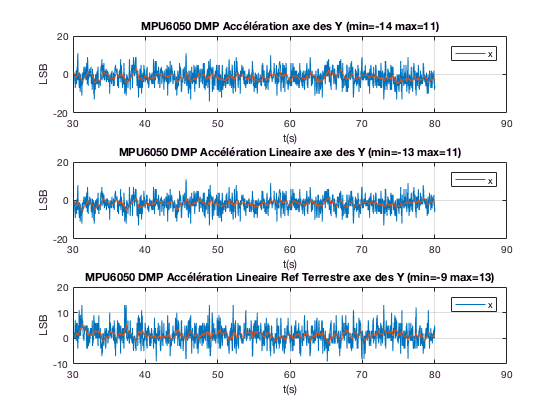

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), sub_accel(:,2), sub_timestamp(:), EMA(sub_accel(:,2),0.1, 0));
str = ['MPU6050 DMP Accélération axe des Y (min=',num2str(min(sub_accel(:,2))),' max=',num2str(max(sub_accel(:,2))), ')'];
title(ax1,str);
legend(ax1, 'x');
grid(ax1, 'on');
ylabel(ax1,'LSB');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), sub_laccel(:,2), sub_timestamp(:),EMA(sub_laccel(:,2),0.1, 0));
str = ['MPU6050 DMP Accélération Lineaire axe des Y (min=',num2str(min(sub_laccel(:,2))),' max=',num2str(max(sub_laccel(:,2))), ')'];
title(ax2,str);
legend(ax2, 'x');
grid(ax2, 'on');
ylabel(ax2,'LSB');
xlabel(ax2,'t(s)');

plot(ax3,sub_timestamp(:), sub_laccelw(:,2), sub_timestamp(:),EMA(sub_laccelw(:,2),0.1, 0));
str = ['MPU6050 DMP Accélération Lineaire Ref Terrestre axe des Y (min=',num2str(min(sub_laccelw(:,2))),' max=',num2str(max(sub_laccelw(:,2))), ')'];
title(ax3,str);
legend(ax3, 'x');
grid(ax3, 'on');
ylabel(ax3,'LSB');
xlabel(ax3,'t(s)');

# Conversion des valeurs brutes de l'accéléromètre

Les valeurs brutes de l'accéléromètre ont été acquise avec un facteur de 8192 LSB/g. (8192 in standard DMP FIFO packet)

## Affichage des valeurs de l'accéléromètre en ${m/s}^2$

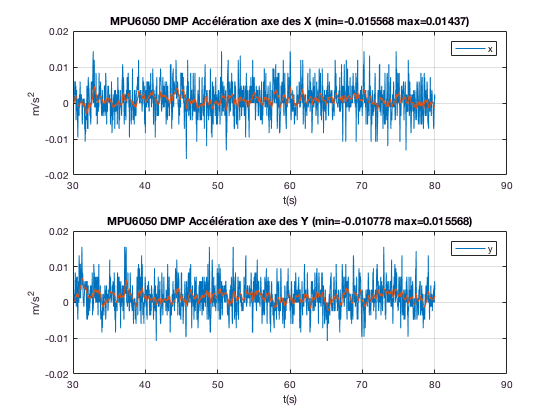

scaledAccel = sub_laccelw(:,1:3) / 8192.0 * 9.81; 
scaledGyro = sub_rawGyro(:, 1:3);

figure; % new figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);
plot(ax1, sub_timestamp(:), scaledAccel(:,1), sub_timestamp(:), EMA(scaledAccel(:,1), 0.1, 0.0));
str = ['MPU6050 DMP Accélération axe des X (min=',num2str(min(scaledAccel(:,1))),' max=',num2str(max(scaledAccel(:,1))), ')'];
title(ax1,str);
legend(ax1, 'x');
grid(ax1, 'on');
ylabel(ax1,'m/s^2');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), scaledAccel(:,2), sub_timestamp(:), EMA(scaledAccel(:,2), 0.1, 0.0));
str = ['MPU6050 DMP Accélération axe des Y (min=',num2str(min(scaledAccel(:,2))),' max=',num2str(max(scaledAccel(:,2))), ')'];
title(ax2,str);
legend(ax2, 'y');
grid(ax2, 'on');
ylabel(ax2,'m/s^2');
xlabel(ax2,'t(s)');

Il semble que malgré l'utilisation du DMP qui minimize le bruit, il y reste quand même un peut de bruit entre -0.021${m/s}^2$ et 0.022${m/s}^2$.

## Affichage des valeurs du gyroscope en  ${º/s}$.

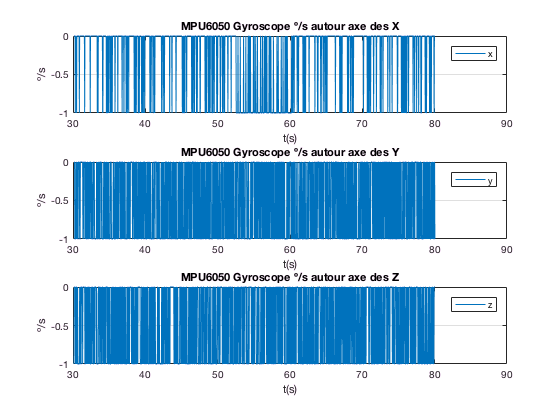

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), scaledGyro(:,1));
title(ax1,'MPU6050 Gyroscope º/s autour axe des X');
legend(ax1, 'x');
grid(ax1, 'on');
ylabel(ax1,'º/s');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), scaledGyro(:,2));
title(ax2,'MPU6050 Gyroscope º/s autour axe des Y');
legend(ax2, 'y');
grid(ax2, 'on');
ylabel(ax2,'º/s');
xlabel(ax2,'t(s)');

plot(ax3,sub_timestamp(:), scaledGyro(:,3));
title(ax3,'MPU6050 Gyroscope º/s autour axe des Z');
legend(ax3, 'z');
grid(ax3, 'on');
ylabel(ax3,'º/s');
xlabel(ax3,'t(s)');

## Affichage des valeurs du magétomètre en  $G$.

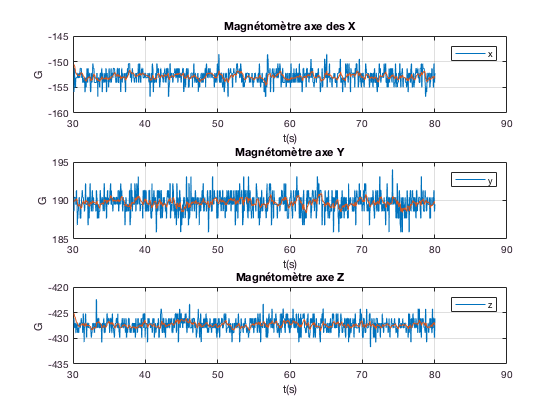

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);
plot(ax1, sub_timestamp(:), sub_rawMag(:,1), sub_timestamp(:),EMA(sub_rawMag(:,1),0.1, -150));
title(ax1,'Magnétomètre axe des X');
legend(ax1, 'x');
grid(ax1, 'on');
ylabel(ax1,'G');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), sub_rawMag(:,2), sub_timestamp(:),EMA(sub_rawMag(:,2),0.1, 190));
title(ax2,'Magnétomètre axe Y');
legend(ax2, 'y');
grid(ax2, 'on');
ylabel(ax2,'G');
xlabel(ax2,'t(s)');

plot(ax3,sub_timestamp(:), sub_rawMag(:,3), sub_timestamp(:),EMA(sub_rawMag(:,3),0.1, -425));
title(ax3,'Magnétomètre axe Z');
legend(ax3, 'z');
grid(ax3, 'on');
ylabel(ax3,'G');
xlabel(ax3,'t(s)');

## Affichage de la direction en º, à partir des valeurs du magétomètre.

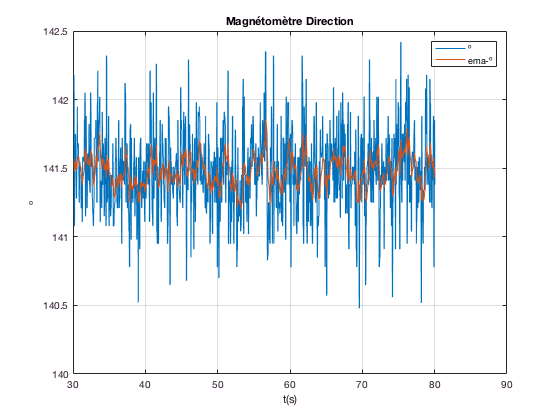

smoothedDir = EMA(sub_heading, 0.1, 141.5) ;
figure
plot(sub_heading(:,2),sub_heading(:,1), sub_heading(:,2), smoothedDir(:,1));
title 'Magnétomètre Direction';
legend({'º', 'ema-º'});
grid 'on';
ylabel 'º';
xlabel 't(s)';

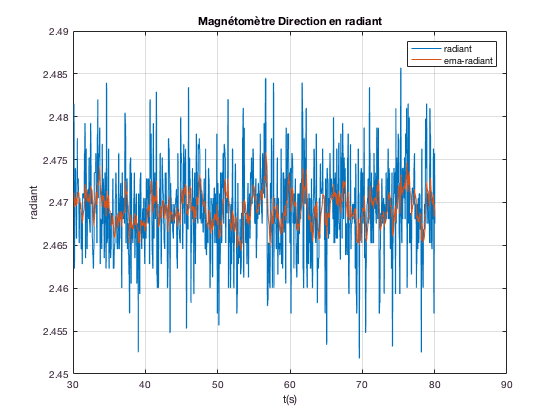

smoothedDir = EMA(sub_heading(:,1)/180.0*pi, 0.1, 2.47) ;
figure
plot(sub_heading(:,2),sub_heading(:,1)/180.0*pi, sub_heading(:,2), smoothedDir(:,1));
title 'Magnétomètre Direction en radiant';
legend({'radiant', 'ema-radiant'});
grid 'on';
ylabel 'radiant';
xlabel 't(s)';

## Affichage des angles d'Euleur à partir des quaternions.

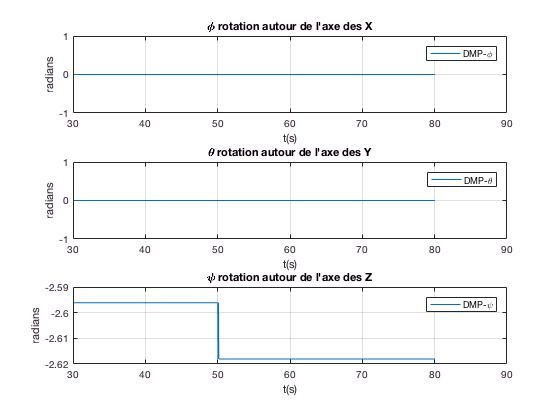

addpath('quaternion_library'); 
euler2 = zeros(length(scaledAccel), 3);
for i = 1:length(scaledAccel)
    euler2(i, :) = quatern2euler(sub_Q(i,1:4));
end

figure; % new figure
ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);

plot(ax1,  sub_timestamp(:), euler2(:,1));
title(ax1,'\phi rotation autour de l''axe des X');
legend(ax1, {'DMP-\phi'});
grid(ax1, 'on');
ylabel(ax1,'radians');
xlabel(ax1,'t(s)');

plot(ax2,sub_timestamp(:), euler2(:,2));
title(ax2,'\theta rotation autour de l''axe des Y');
legend(ax2, { 'DMP-\theta'});
grid(ax2, 'on');
ylabel(ax2,'radians');
xlabel(ax2,'t(s)');

plot(ax3, sub_timestamp(:), euler2(:,3));
title(ax3,'\psi rotation autour de l''axe des Z');
legend(ax3, {'DMP-\psi'});
grid(ax3, 'on');
ylabel(ax3,'radians');
xlabel(ax3,'t(s)');

L'on observe la dérive de l'intégration des valeurs du gyroscope pour la rotation autour de l'axe des Z. Un algorithme de fusion des données de l'accéléromètre, du gyroscope et du magnétomètre permeterait de minimizer cette effect telque l'algorithme de Madgwick. Une autre option est d'utiliser une IMU qui fusionnera tous ces données à l'intérieur du module telque la série des MPU-9050.